# 12. Plotting

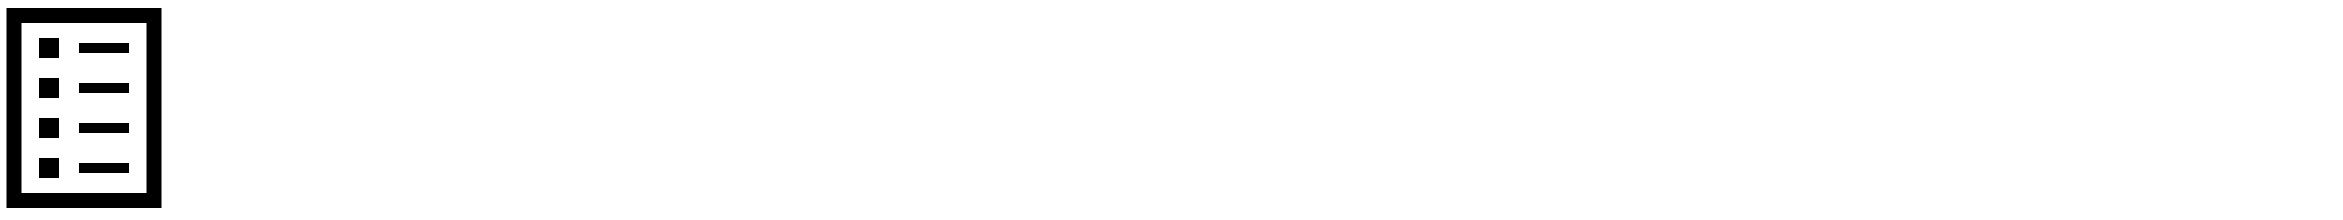

A plot is a visual representation of the data and is especially valuable to analyze data graphically. You can plot with the `plot(x,y)` function.

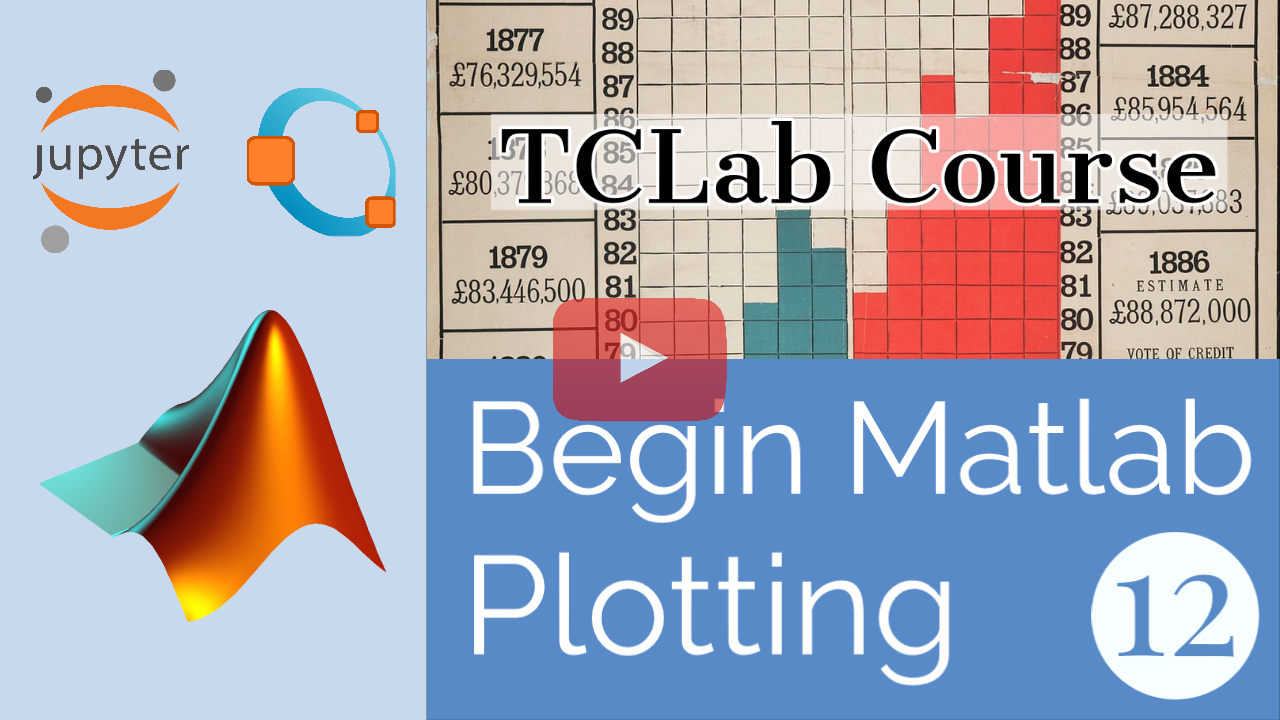

[Click here to watch the video.](https://www.youtube.com/watch?v=VezzTS9P1Tk&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

In the incubator example, we may want to see how the temperature changes with time. The `x`-axis may be **time** and `y`-axis may be the **data**. In an incubator, graphs could be used for a number of things. Some could be heater percentage, egg temperature, and much more.

In the code below, graphs can have lines that are formatted as dashed lines:

Changing values for `x` and `y` will change the points that are plotted for the lines. The `r` means that the line is red and the `--` means that the same line is dashed. Here is a list of additional line modifiers to change the color, data marker style, and line style.

`     ---- Color ----     ---- Data Style ----    ---- Line Style ---- `

`     b     blue          .     point              -       solid `

`     g     green         o     circle             :       dotted `

`     r     red           x     x-mark             -.      dashdot  `

`     c     cyan          +     plus               --      dashed    `

`     m     magenta       *     star               (none)  no line `

`     y     yellow        s     square `

`     k     black         d     diamond `

`     w     white         v     triangle (down) `

`                         h     hexagram `

`                         p     pentagram `

`                         ^     triangle (up) `

`                         <     triangle (left) `

`                         >     triangle (right)`

Use the `hold on` command to not replace the prior line.

x = [1, 2, 3, 4]; % Times

y = [3, 4, 2, 6]; % Array with data
z = [5, 1, 8, 3]; % Array with data

plot(x,y) % Plots a graph with the list
hold on
plot(x,z,'r--') % 'r--' changes line to red, and to a dashed line

## **Help Command**

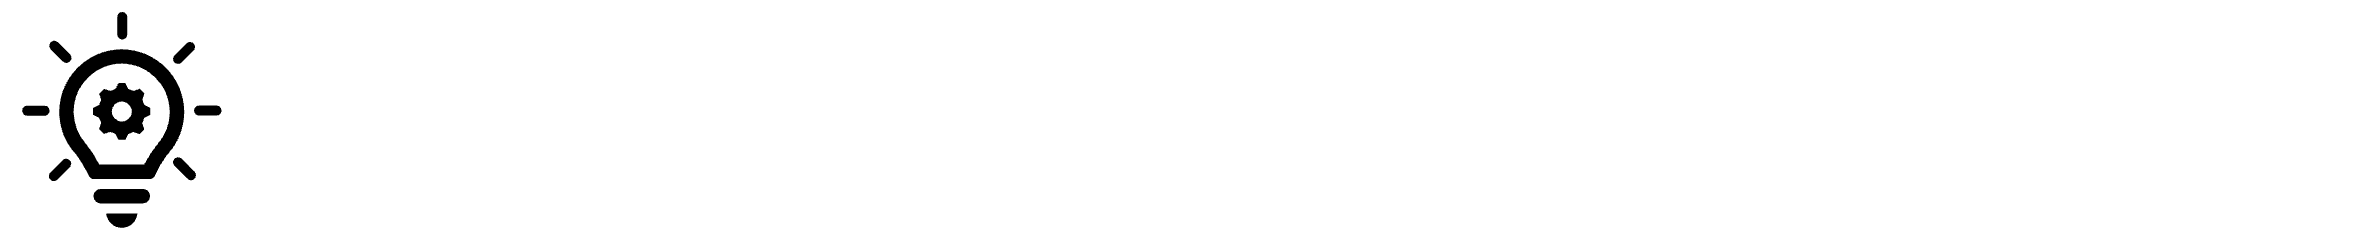

You can see all available functions by running the code `help plot`. You can also use the `help` for any other function.

help plot

## Activity

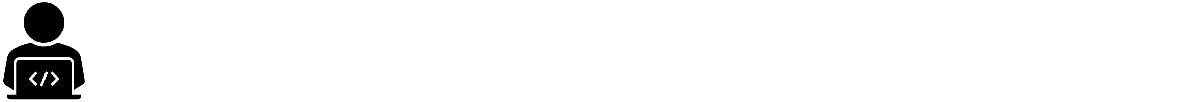

Make a plot using 3 lines with 5 data points each.

Use this data to plot (time, x), (time,y), and (time,z). Use the plotting examples or the plotting help above if you need help.

time = [1, 2, 3, 4, 5];
x = [5,4,0,2,3];
y = [3,-1,4,6,8];
z = [1,2,4,8,9];

**Customizing Plots**

Plots are customized with labels (x-label, y-label, title, legend) with more lines of code such as:

There are other ways to modify the plot such as adjusting the range of `y` values (`ylim()`) or range of `x` values (`xlim()`). Each function modifies the plot and they can be used in any order.

You can also create sub-plots by first telling what grid size you'd like to use. In this case, we have 2 rows and 1 column with:

The third number (1) indicates that we are now plotting in the first sub-plot on top. When we give another command:

to begin making modifications to the bottom subplot.

**Exporting Plots**

Plots can be exported as a static figure or animated to create a movie.

A plot is exported by using the function:

(Common file extensions for export are `.png`, `.jpg`, and `.eps`. Changing the name of the file extension changes the type and size of the file export. Portable Network Graphics(`.png`) files work well for import into a presentation or into a report document.) Encapsulated postscript (`.eps`) is best for inserting figures into technical documents (especially LaTeX).

**Where did it save the file?**

Sometimes it can be hard to find the directory where the figure is saved. You can display your current run folder by running the following command.

disp(["Figure saved in current directory: ",pwd])

## **Activity**

Try the code below to add a title, x-label, and y-label.

Adjust the `y` range to be between `-1` and `1.2`. Adjust the `x` range to be between `0` and `5`.

The legend (`legend`) gets values to run from lines `plot(label='Your label')`.

**Bonus:** Split the two plots into two subplots.


x = linspace(0,6,100); % (starting point, end point, how many points total)
y = sin(x);
z = cos(x);

title('Put title here') % Add a title

plot(x,y, 'r--', linewidth,5) % linewidth modifies the width of a line
hold on
plot(x,z, 'k:', linewidth,5) % label gives the line a label

legend('y=sin(x)','What is a good label?') % Values given to legend

xlim([0, 3])      % Set the x range: 0 to 5
ylim([-1.5, 1.5]) % Set the y range: -1 to 1.2

ylabel('Change y label')
xlabel('Change x label')

Make a plot that comes from the lab's temperatures, 30 seconds of data. The code below sets heater one to 70 percent and heater two to 100 percent. It collects data for 30 seconds in the lists `tm`=Time, `T1`=Temperature 1, and `T2`=Temperature 2.

lab = tclab;

% initialize lists
tm = []; T1 = []; T2 = [];

% turn on heaters
lab.Q1(70); lab.Q2(100);

% collect data for 30 seconds
for i = 1:30
    tm(i) = i;
    T1(i) = lab.T1;
    T2(i) = lab.T2;
    disp([i,T1(i),T2(i)])
    pause(1)
end
lab.off(); clear lab

Make the plotting lines modified to your liking. Because you're using two heaters, you should have two lines to represent the two temperatures. Use what programming principles are necessary, and if needed review some basics.

plot(tm,T1,'r--')
hold on
% add plot for temperature 2

legend('T1','T2')
xlabel('Add x-label')
ylabel('Add y-label')
print -dpng 12-temperatures.png